# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.12 matlab如何展示最大值的等高线？

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/623413949](https://www.zhihu.com/question/623413949)

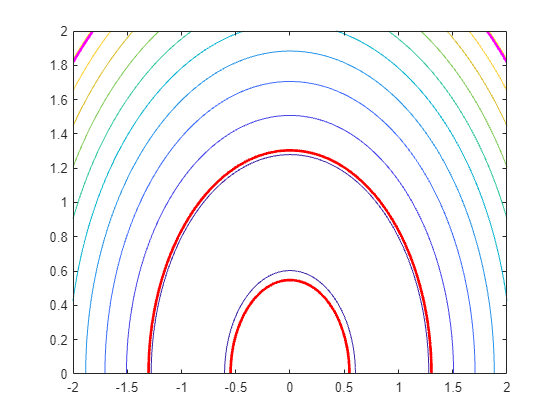

clear; clc;
kappa = 1;
gamma_m = kappa;
delta_10 = (-2:0.01:2)*kappa;
J_10 = (0:0.01:2)*kappa;
[x, y] = meshgrid(delta_10, J_10);
R_l = abs(x.^2 - kappa^2 + y.^2);
minValue = min(R_l(:));
maxValue = max(R_l(:));
thr1 = minValue + (maxValue - minValue) / 10;
thr2 = maxValue - (maxValue - minValue) / 10;
contour(x, y, R_l, 10);
hold on
contour(x, y, R_l, [thr1, thr1], 'LineWidth', 2, 'EdgeColor', 'r');
contour(x, y, R_l, [thr2, thr2], 'LineWidth', 2, 'EdgeColor', 'm');
hold off